# Thermodynamics of N-Schlogl

%specify roots
roots = [ 1 2 2.4 ]

roots =     1.0000    2.0000    2.4000


%get rate from roots
poly = -1;
x = sym('x');
for i = 1:size(roots,2)
    poly = poly*(x-roots(i));
end

poly_func = matlabFunction(poly)

poly_func = function_handle with value:
    @(x)-(x-1.0).*(x-2.0).*(x-1.2e+1./5.0)


%Get rate cosntants 
C = coeffs(poly)

$$C = \left(\begin{array}{cccc} 4.8000 & -9.2000 & 5.4000 & -1 \end{array}\right)$$

k_const = abs(C)

$$k\_const = \left(\begin{array}{cccc} 4.8000 & 9.2000 & 5.4000 & 1 \end{array}\right)$$

%get forward and backward rates
rplus = 0;
rmin = 0;

for i = 1:size(k_const,2)
    if mod(i,2) == 0
        rmin = rmin + k_const(i)*x^(i-1);
    else 
        rplus = rplus + k_const(i)*x^(i-1);
    end
end
rpoly = rplus - rmin;

%verify rate from roots and rate cosntants is the same
simplify(rpoly-poly)

$$ans = 0$$

%rate across each reaction
r_rxn = [];
%potential change across each reaction
G_rxn = [];

for i = 1:size(k_const,2)/2
     r_rate = k_const(2*i - 1)*x^(2*i-2) -  k_const(2*i)*x^(2*i-1);
    r_rxn = [r_rxn; r_rate];
    G_rxn = [G_rxn; log(rmin/rplus)*r_rate];
end
r_rxn

$$r\_rxn = \left(\begin{array}{c} 4.8000-9.2000\,x\\ 5.4000\,x^{2}-x^{3} \end{array}\right)$$

G_rxn

$$G\_rxn = \left(\begin{array}{c} -\log\left(\frac{x^{3}+9.2000\,x}{5.4000\,x^{2}+4.8000}\right)\,\left(9.2000\,x-4.8000\right)\\ \log\left(\frac{x^{3}+9.2000\,x}{5.4000\,x^{2}+4.8000}\right)\,\left(5.4000\,x^{2}-x^{3}\right) \end{array}\right)$$

r_rxn_func = matlabFunction(r_rxn)

r_rxn_func = function_handle with value:
    @(x)[x.*(-4.6e+1./5.0)+2.4e+1./5.0;x.^2.*(2.7e+1./5.0)-x.^3]


G_rxn_func = matlabFunction(G_rxn)

G_rxn_func = function_handle with value:
    @(x)[-log((x.*(4.6e+1./5.0)+x.^3)./(x.^2.*(2.7e+1./5.0)+2.4e+1./5.0)).*(x.*(4.6e+1./5.0)-2.4e+1./5.0);log((x.*(4.6e+1./5.0)+x.^3)./(x.^2.*(2.7e+1./5.0)+2.4e+1./5.0)).*(x.^2.*(2.7e+1./5.0)-x.^3)]


%total dissipation
diss = log(rmin/rplus)*poly;
diss_func = matlabFunction(diss);

%plots
x_arr = min(roots):min(roots)/10: max(abs(roots));

%rate plots
figure()
hold on
label_lst = 1:size(r_rxn,1);
for i = 1:size(r_rxn,2)
    plot(x_arr,r_rxn_func(x_arr))
end
plot(x_arr,poly_func(x_arr),'k')
yline(0,'--')
%ylim([-0.5 0.5])
label_lst =[label_lst "total"]

label_lst = 1×3 string array
    "1"    "2"    "total"


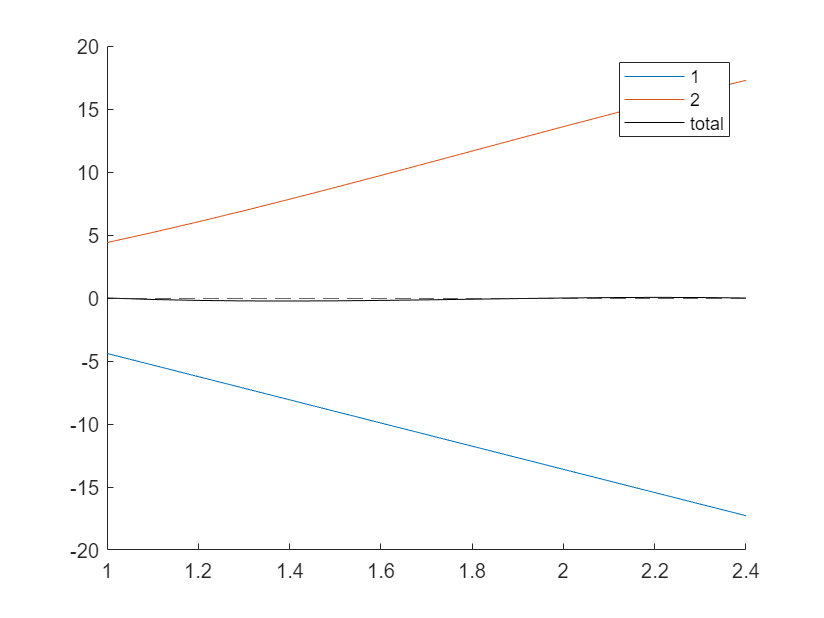

legend(string(label_lst))

%dissipation plots
figure()
hold on
label_lst = 1:size(r_rxn,1);
for i = 1:size(r_rxn,2)
    plot(x_arr,G_rxn_func(x_arr))
end
plot(x_arr,diss_func(x_arr),'k')
yline(0,'--')
%ylim([-0.5 0.5])
label_lst =[label_lst "total"]

label_lst = 1×3 string array
    "1"    "2"    "total"


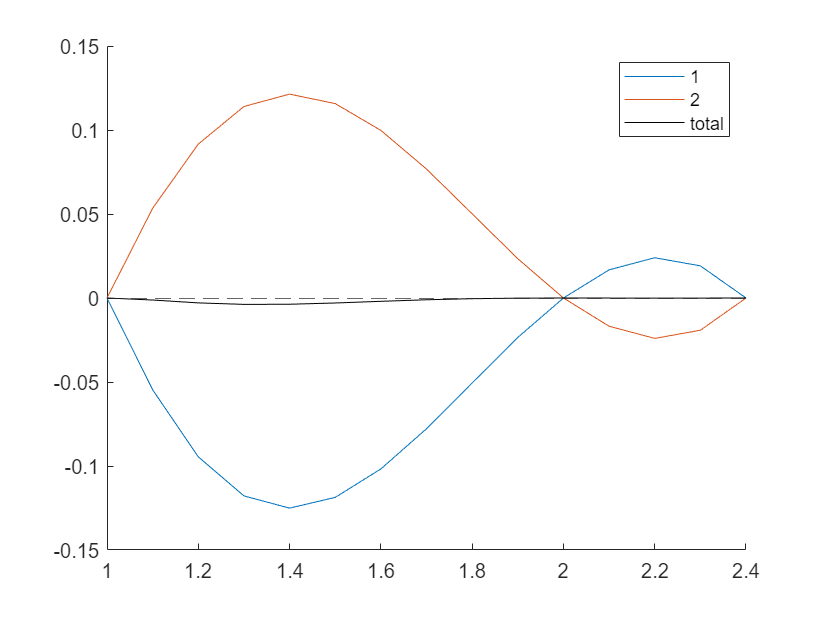

legend(string(label_lst))

label_lst = 1:size(r_rxn,1)

label_lst =      1     2
